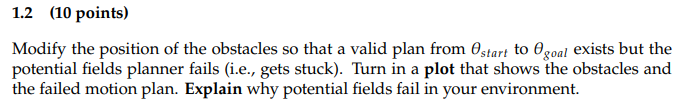

clear
close all

% Start and goal environments
theta_start= [0; 0];
theta_goal = [1; 1];

% Modified obstacle positions and sizes
obs_c21 = [0.3; 0.5];  % Shifted first obstacle closer to the second
obs_r21 = 0.15;        % Slightly increased radius
obs_c22 = [0.8; 0.5];  % Shifted second obstacle closer to the first
obs_r22 = 0.25;        % Slightly increased radius

% Visualize the environment
figure
grid on
hold on
axis([0, 1, 0, 1])
axis equal
viscircles(obs_c21', obs_r21, 'Color', [0.5, 0.5, 0.5]);
viscircles(obs_c22', obs_r22, 'Color', [0.5, 0.5, 0.5]);
plot(0, 0, 'ko', 'MarkerFaceColor', 'k');
plot(1, 1, 'ko', 'MarkerFaceColor', 'k');

% Setting the variables
alpha= 0.01;
epsilon = 0.1;
delta= 0.01;

% Initial trajectory
theta(:,1) = theta_start;
t=1;
del_Unet=1;

while norm(del_Unet) > epsilon
    del_Ux= U_theta(theta(:,t) + [delta;0]);
    del_Uy= U_theta(theta(:,t)+ [0;delta]);
    del_U= U_theta(theta(:,t));

    del_Unet=[del_Ux-del_U; del_Uy-del_U]/delta;

    theta(:,t+1)= theta(:,t)- alpha*del_Unet;
    t=t+1;
end

     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



     0



    0.0300



     0



     0



     0



     0



     0



     0



     0



    0.0235



    0.0135



    0.0028



    0.0058



    0.0016



     0



    0.0471



    0.0589



    0.0118



     0



     0



     0



     0



     0



     0



    0.0293



    0.0172



    0.0047



    0.0017



    0.0238



     0



    0.0051



    0.0015



     0



    0.0499



    0.0338



    0.0138



     0



    0.0034



     0



    0.0124



    0.0128



   1.1985e-04



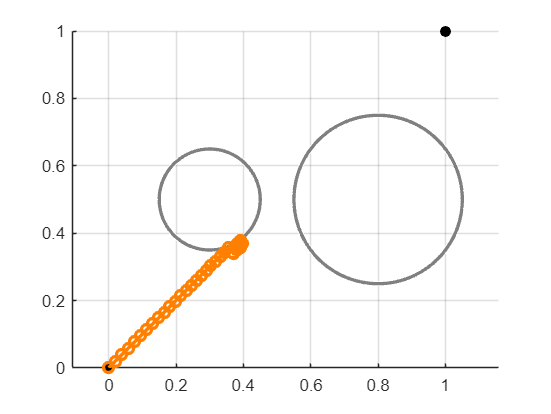



grid on
hold on
axis equal
plot(theta(1,:), theta(2,:), 'o-',...
    'Color', [1, 0.5, 0], 'LineWidth', 2);

function U = U_theta(theta) 
    beta=2;
    gamma=1;
    theta_goal = [1; 1];
    % Modified obstacle positions and sizes
    obs_c21 = [0.3; 0.5];  % Update obstacle parameters
    obs_r21 = 0.15;
    obs_c22 = [0.6; 0.5];
    obs_r22 = 0.25;

    Urep1=0;
    Urep2=0;

    Uatt=0.5*beta*norm(theta_goal-theta)^2;    

    if norm(obs_c21-theta)<= obs_r21
        Urep1=0.5* gamma*((1/norm(obs_c21-theta))- (1/obs_r21))^2;
    end
    if norm(obs_c22-theta)<= obs_r22
        Urep2= 0.5*gamma*((1/norm(obs_c22-theta))- (1/obs_r22))^2;
    end

    Urep= Urep1+ Urep2;
    disp(Urep);
    U= Uatt + Urep;
end

In this modification, the obstacles are placed closer to each other, potentially creating a narrow corridor that the drone might not be able to navigate due to the combined repulsive forces. This setup can result in the planner getting stuck in a** local minimum**, where the drone is unable to progress towards the goal. Thus, we place a local minimim in between the start and goal.  Gradient descent can only climb "down" so if **it's surrounded by high gradients**, it can't escape.